clear all;
clc;

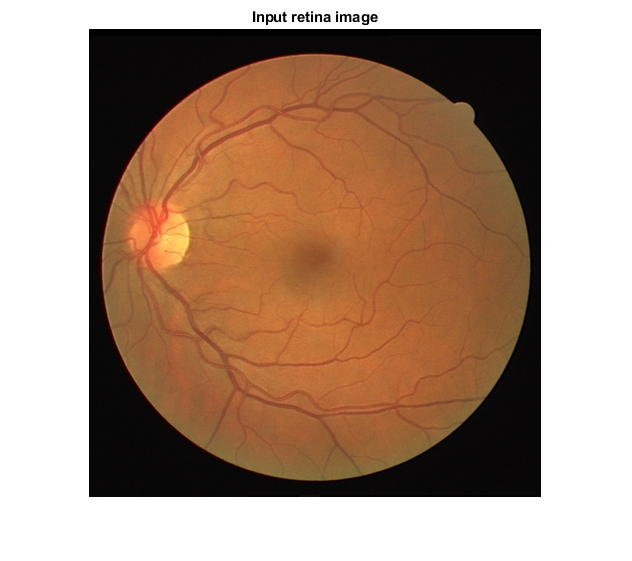

I = imread('retina_images\1.tif');
I = imresize(I,.8);
figure, imshow(I);title('Input retina image');

input = rgb2gray(I);

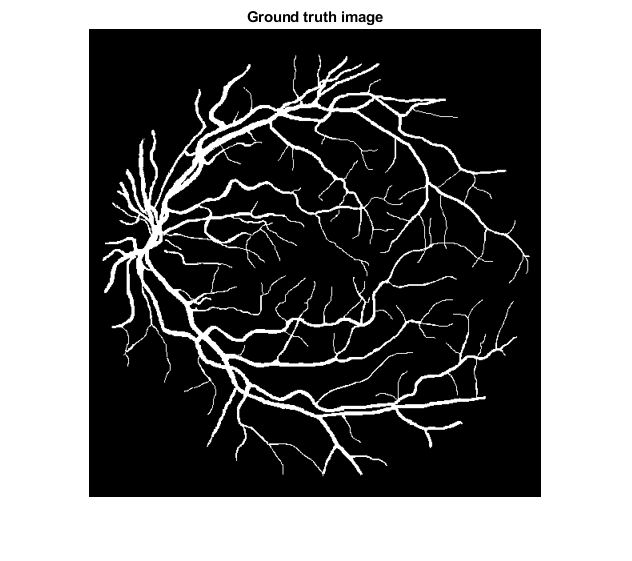

gt1 = imread('label_images\1.tif');
gt1 = imresize(gt1,.8);
gt_image = im2bw(gt1);
figure, imshow(gt1);title('Ground truth image');

figure,imshow(segmentRetina(I)),title("Segmented Image without processing")

Error using adapthisteq
Expected input number 1, I, to be two-dimensional.

Error in adapthisteq>parseInputs (line 418)
validateattributes(I, {'uint8', 'uint16', 'double', 'int16', 'single'}, ...

Error in adapthisteq (line 157)
 noPadRect, distribution, al

% segmented_image = segmentRetina(input);
segmented_image1 = segmentRetina(input,32,0.35, 0.7);
segmented_image2 = segmentRetina(input,64,0.35, 0.7);
segmented_image3 = segmentRetina(input,32,0.2, 0.8);
segmented_image4 = segmentRetina(input,64,0.2, 0.8);
segmented_image5 = segmentRetina(input,128,0.2, 0.8);

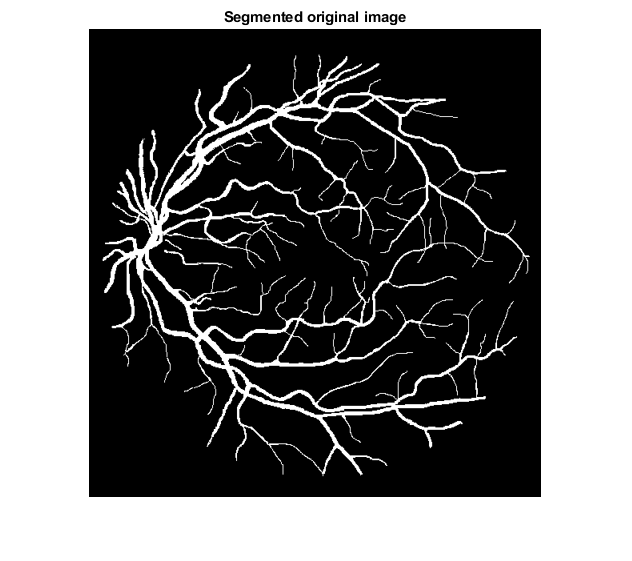

figure,imshow(gt1);title('Segmented original image');

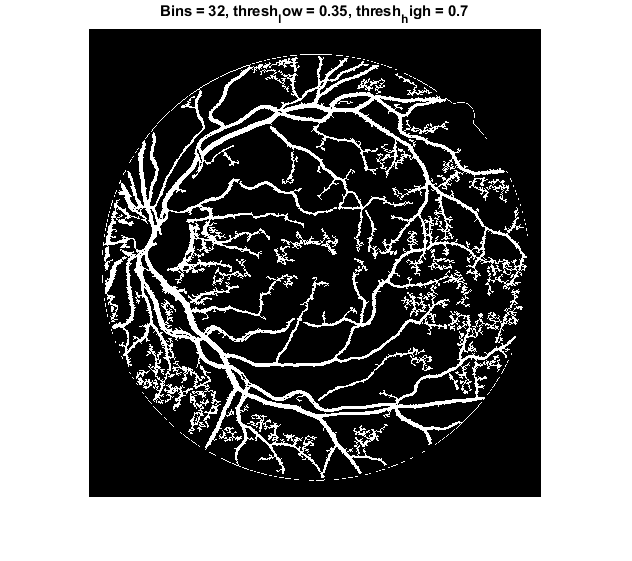

figure,imshow(segmented_image1);title('Bins = 32, thresh_low = 0.35, thresh_high = 0.7');

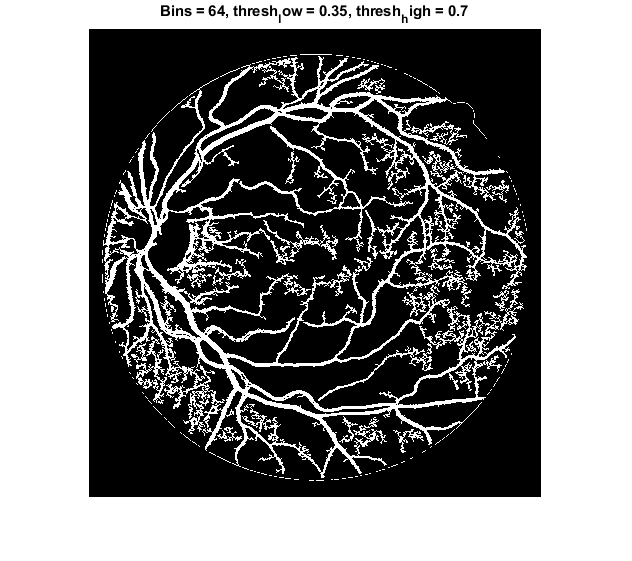

figure,imshow(segmented_image2);title('Bins = 64, thresh_low = 0.35, thresh_high = 0.7');

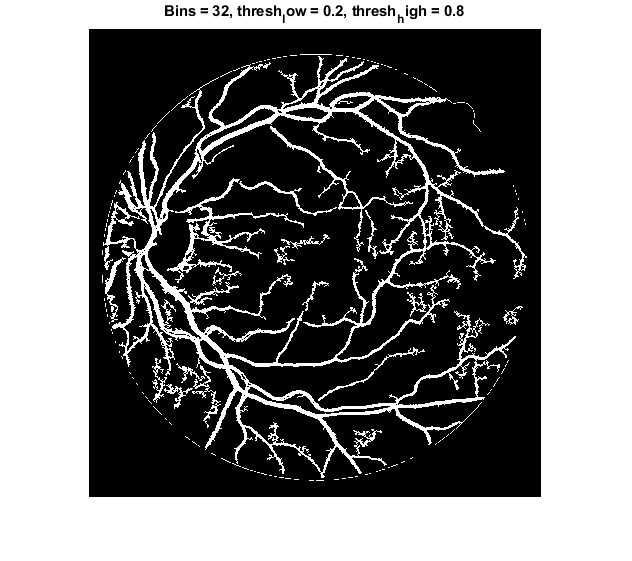

figure,imshow(segmented_image3);title('Bins = 32, thresh_low = 0.2, thresh_high = 0.8');

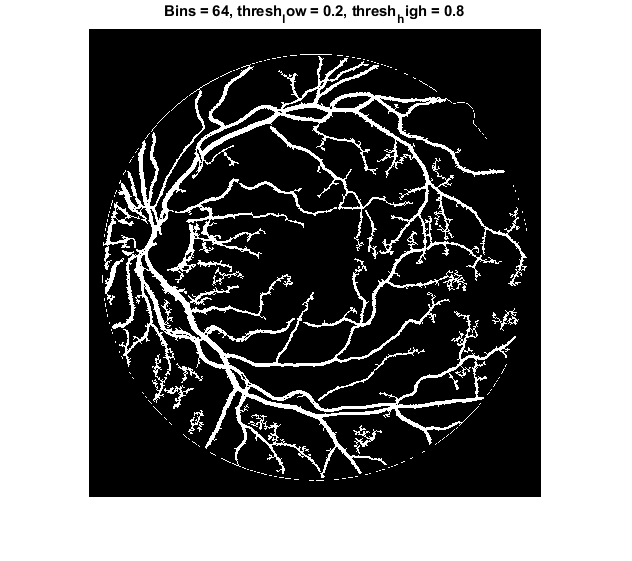

figure,imshow(segmented_image4);title('Bins = 64, thresh_low = 0.2, thresh_high = 0.8');

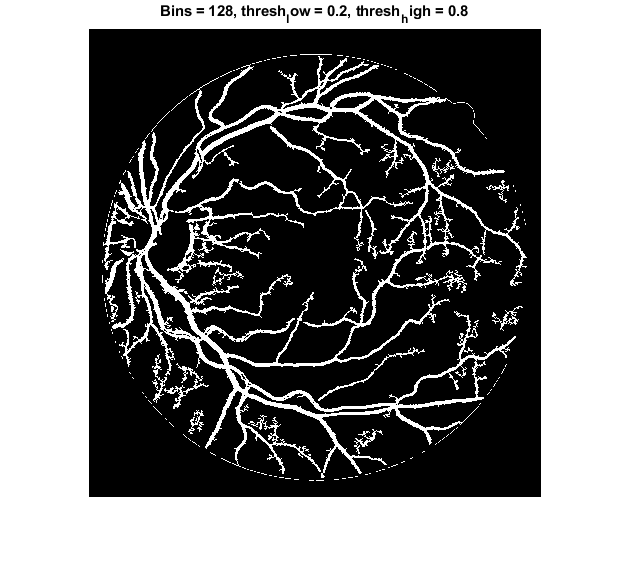

figure,imshow(segmented_image5);title('Bins = 128, thresh_low = 0.2, thresh_high = 0.8');

% Calculate evaluation metrics for each segmented image
[P1, N1, T1] = calculatePNT(segmented_image1, gt_image);
[P2, N2, T2] = calculatePNT(segmented_image2, gt_image);
[P3, N3, T3] = calculatePNT(segmented_image3, gt_image);
[P4, N4, T4] = calculatePNT(segmented_image4, gt_image);
[P5, N5, T5] = calculatePNT(segmented_image5, gt_image);


% Display the evaluation metric values
fprintf('Bins = 32, thresh_low = 0.35, thresh_high = 0.7\n');

Bins = 32, thresh_low = 0.35, thresh_high = 0.7


fprintf('Value of P is: %.2f\n', P1);

Value of P is: 81.78


fprintf('Value of N is: %.2f\n', N1);

Value of N is: 92.34


fprintf('Value of T is: %.2f\n', T1);

Value of T is: 91.39



fprintf('\nBins = 64, thresh_low = 0.35, thresh_high = 0.7:\n');


Bins = 64, thresh_low = 0.35, thresh_high = 0.7:


fprintf('Value of P is: %.2f\n', P2);

Value of P is: 83.07


fprintf('Value of N is: %.2f\n', N2);

Value of N is: 90.75


fprintf('Value of T is: %.2f\n', T2);

Value of T is: 90.07



fprintf('\nBins = 32, thresh_low = 0.2, thresh_high = 0.8:\n');


Bins = 32, thresh_low = 0.2, thresh_high = 0.8:


fprintf('Value of P is: %.2f\n', P3);

Value of P is: 79.68


fprintf('Value of N is: %.2f\n', N3);

Value of N is: 94.91


fprintf('Value of T is: %.2f\n', T3);

Value of T is: 93.55



fprintf('\nBins = 64, thresh_low = 0.2, thresh_high = 0.8:\n');


Bins = 64, thresh_low = 0.2, thresh_high = 0.8:


fprintf('Value of P is: %.2f\n', P4);

Value of P is: 79.42


fprintf('Value of N is: %.2f\n', N4);

Value of N is: 95.22


fprintf('Value of T is: %.2f\n', T4);

Value of T is: 93.80



fprintf('\nBins = 128, thresh_low = 0.2, thresh_high = 0.8:\n');


Bins = 128, thresh_low = 0.2, thresh_high = 0.8:


fprintf('Value of P is: %.2f\n', P5);

Value of P is: 79.38


fprintf('Value of N is: %.2f\n', N5);

Value of N is: 95.15


fprintf('Value of T is: %.2f\n', T5);

Value of T is: 93.74
